# Case 1

## 1

clear all
load('Opgave1_audiofil.mat');
length(audio)

ans = 1409024

n = 1:length(audio);

fs = 44100;

## 2

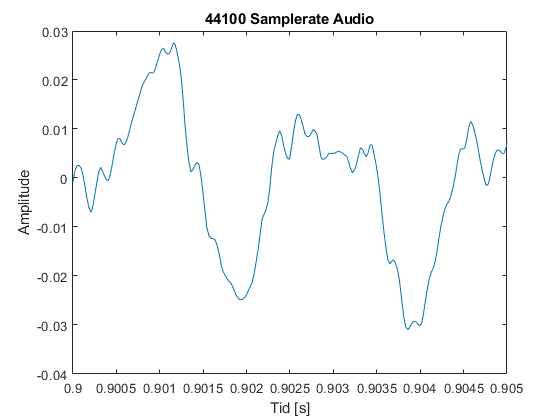

figure(1)
plot(n / fs, audio);
xlabel('Tid [s]');
ylabel('Amplitude');
title('44100 Samplerate Audio');
xlim([0.9, 0.905]);

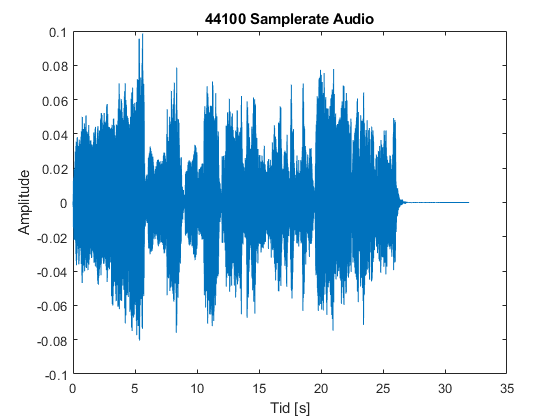


figure(5)
plot(n / fs, audio);
xlabel('Tid [s]');
ylabel('Amplitude');
title('44100 Samplerate Audio');

## 3

maksimum = max(audio)

maksimum = 0.0985

minimum = min(audio)

minimum = -0.0804

gennemsnit = mean(audio)

gennemsnit = -1.4752e-05

RMS = rms(audio)

RMS = 0.0154

effekt = RMS^2

effekt = 2.3731e-04

energi = effekt * length(audio)

energi = 334.3711

## 4

peak = max(abs(audio))

peak = 0.0985

crestfactor = peak / RMS

crestfactor = 6.3968

## 5

figure(2)
fs_nedsamplet = fs / 4

fs_nedsamplet = 11025

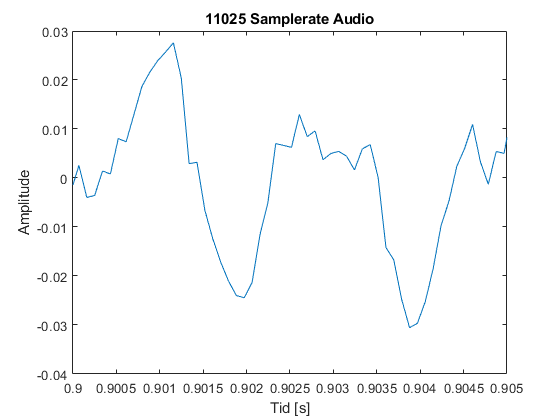

plot(n([1:4:length(n)]) / fs, audio([1:4:length(audio)]));
xlabel('Tid [s]');
ylabel('Amplitude');
title('11025 Samplerate Audio');
xlim([0.9, 0.905]);

## 6

soundsc(audio, fs);
pause(27);

soundsc(audio([1:4:length(audio)]), fs_nedsamplet)
pause(27);

## 7

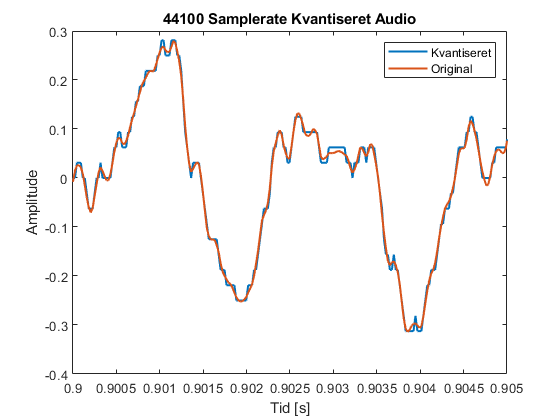

audio_quantised = quantise_n_bits(audio / maksimum, 5);
audio_quantised = audio_quantised;
figure(3);
plot(n / fs, audio_quantised, n / fs, audio / maksimum, 'LineWidth', 1.5);
xlabel('Tid [s]');
ylabel('Amplitude');
title('44100 Samplerate Kvantiseret Audio');
legend('Kvantiseret', 'Original');
xlim([0.9, 0.905]);

## 8

soundsc(audio_quantised, fs)
pause(27);

## 9

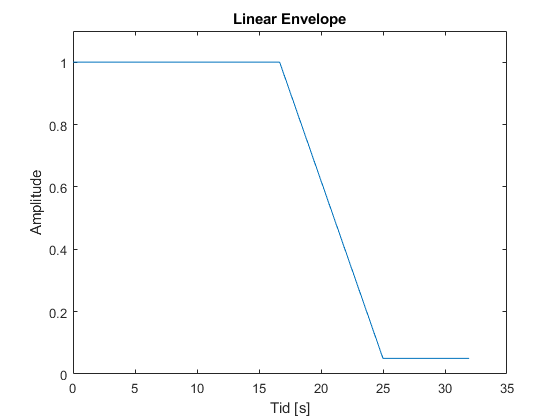

% Amount of samples till audio goes silent
n_samp = 25*fs;

% Fill the vector envel with 1 with a size of n_samp*(2/3)
envel = zeros(1, floor(n_samp * (2/3))) + 1;

% dA is the amplitude change per step to linearly go from 1 to 0.05 over
% n_samp*(1/3) steps
dA = 0.95 / (floor(n_samp * (1/3)));
envel = [envel, 1:-dA:0.05];

% Fill the rest of envel with 0.05
envel = [envel, zeros(1, length(audio) - length(envel)) + 0.05];

% Multiply envel elementwise with the audio to fade the audio out
audio_envelope = envel.*audio';


figure(4);
plot(n / fs, envel);
xlabel('Tid [s]');
ylabel('Amplitude');
title('Linear Envelope');
ylim([0,1.1]);

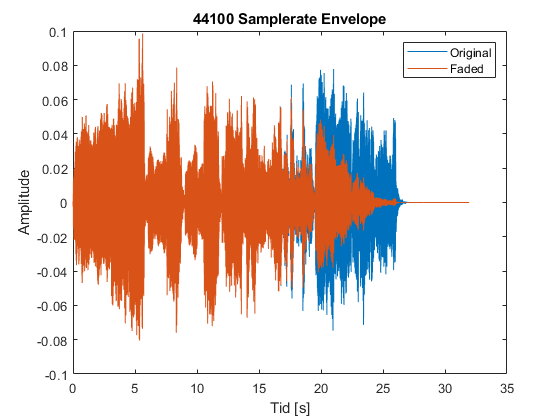


figure(3);
plot(n / fs, audio, n / fs, audio_envelope);
xlabel('Tid [s]');
ylabel('Amplitude');
title('44100 Samplerate Envelope');
legend('Original', 'Faded');

soundsc(audio_envelope, fs);